clear; clc;
load('..\ECG_with_noise.mat');

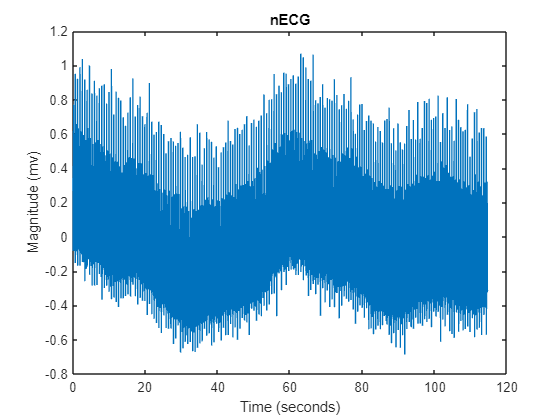

fs = 500;  
T = 1/fs;  
num_points = size(nECG, 2);
time_axis = linspace(0, T * (num_points-1), num_points); 

plot(time_axis,nECG);
xlabel("Time (seconds)");
ylabel("Magnitude (mv)");
title("nECG");

Initializing Window Designer....

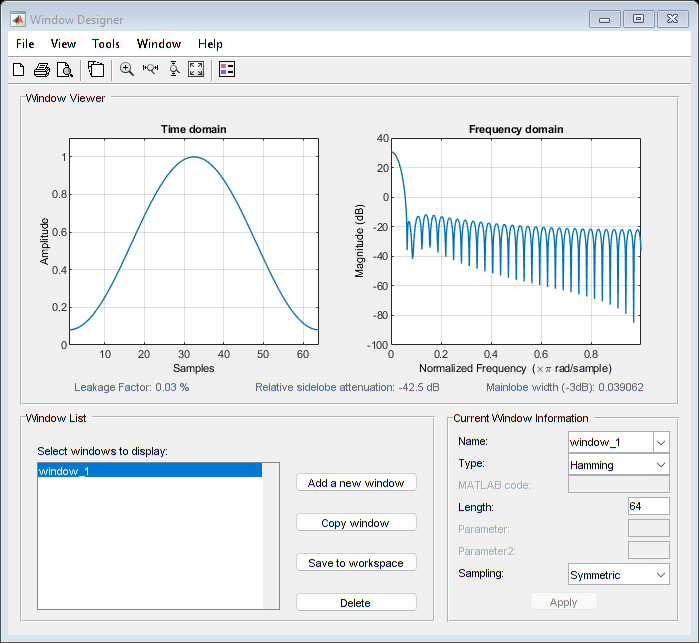

. done. 


nfft = num_points;
[pxx_nECG,f_nECG] = periodogram(nECG,window,nfft,fs);

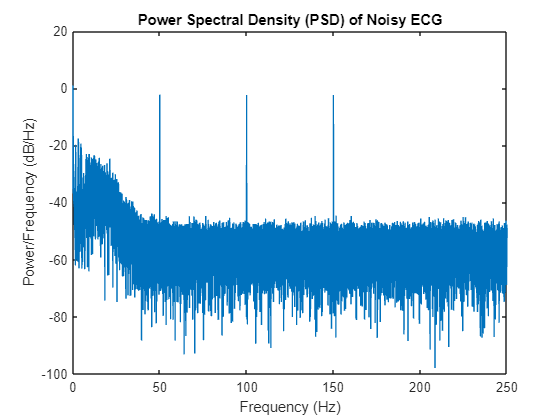

figure;
plot(f_nECG, 10*log10(pxx_nECG)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of Noisy ECG');

Designing of Low Pass Filter

delta = 0.001;  % minimum attenuation in the stopband OR maximum ripple in the passpand

%considering low pass filter
fpass = 110;
fstop = 140;
fc = 125;

wp = (2*pi*fpass/fs);
ws = (2*pi*fstop/fs);

delta_w = abs(ws-wp);

A = -20*log10(delta);
M = ceil((A-8)/(2.285*delta_w));

if A >50
    beta = 0.1102*(A-8.7);
elseif 21<= low_A <= 50
    beta = 0.5842*((A-21)^(0.4))+0.07886*(A-21);
else
    beta = 0;
end

fprintf('For the low pass filter, Order (M) = %.0f\nBeta = %.3f\n', M,beta);

For the low pass filter, Order (M) = 61
Beta = 5.653


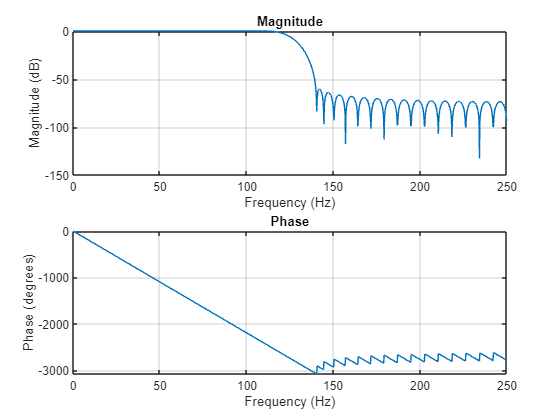


win = kaiser(M+1, beta);

flag = 'scale';
b_low  = fir1(M, fc/(fs/2), 'low', win, flag);
Low_pass_filter_Hd = dfilt.dffir(b_low);

freqz(b_low,1,1024,500);

Designing of High Pass filter

delta = 0.01;  

%considering high pass filter
fpass = 2;
fstop = 8;
fc = 5;

wp = (2*pi*fpass/fs);
ws = (2*pi*fstop/fs);

delta_w = abs(ws-wp);

A = -20*log10(delta);
M = ceil((A-8)/(2.285*delta_w));

if A >50
    beta = 0.1102*(A-8.7);
elseif 21<= A <= 50
    beta = 0.5842*((A-21)^(0.4))+0.07886*(A-21);
else
    beta = 0;
end

fprintf('For the high pass filter, Order (M) = %.0f\nBeta = %.3f\n', M,beta);

For the high pass filter, Order (M) = 186
Beta = 3.395


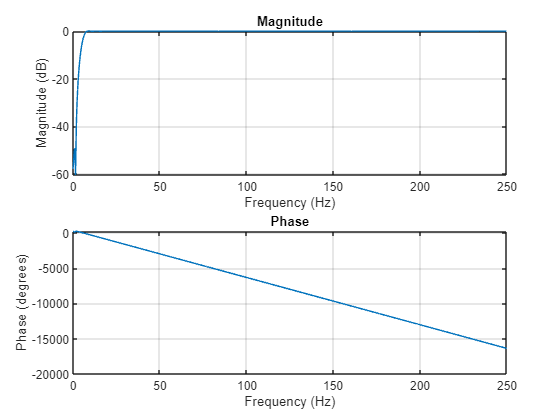


win = kaiser(M+1, beta);

flag = 'scale';
b_high  = fir1(M, fc/(fs/2), 'high', win, flag);
high_pass_filter_Hd = dfilt.dffir(b_high);

freqz(b_high,1,1024,fs);

Comb filter

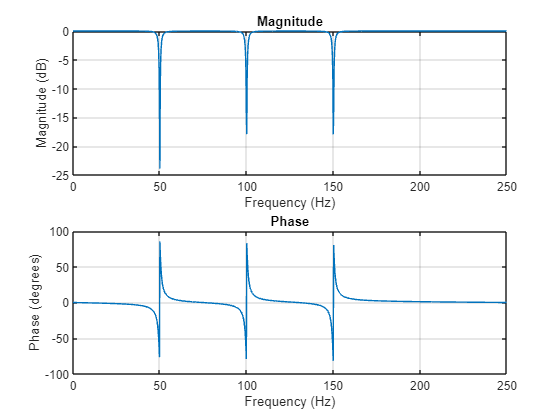

Fnotch1 = 50;   % Notch Frequency 1
BW1 = 3;        % Bandwidth 1
Apass1 = 1;     % Bandwidth Attenuation 1
[b1, a1] = iirnotch(Fnotch1 / (fs/2), BW1 / (fs/2), Apass1);

Fnotch2 = 100;  % Notch Frequency 2
BW2 = 3;        % Bandwidth 2
Apass2 = 1;     % Bandwidth Attenuation 2
[b2, a2] = iirnotch(Fnotch2 / (fs/2), BW2 / (fs/2), Apass2);

Fnotch3 = 150;  % Notch Frequency 3
BW3 = 3;        % Bandwidth 3
Apass3 = 1;     % Bandwidth Attenuation 3
[b3, a3] = iirnotch(Fnotch3 / (fs/2), BW3 / (fs/2), Apass3);

% finaly the comb filter
b_comb = conv(conv(b1, b2), b3);
a_comb = conv(conv(a1, a2), a3);

freqz(b_comb, a_comb, 1024, fs);

after_low_pass = filter(b_low,1,nECG);
group_delay_low_pass = round(mean(grpdelay(b_low,1)));
after_low_pass(1:group_delay_low_pass) = [];

after_high_pass = filter(b_high,1,after_low_pass);
group_delay_high_pass = round(mean(grpdelay(b_high,1)));
after_high_pass(1:group_delay_high_pass) = [];

after_comb = filter(b_comb,a_comb,after_high_pass);

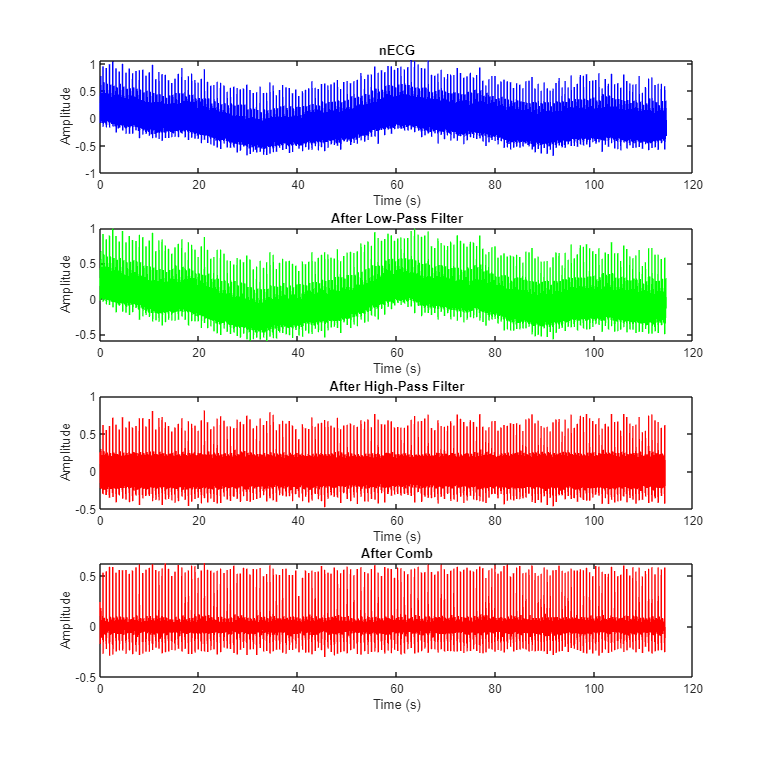


figure();

n1 = 500;
n2 = 5000;
set(gcf, 'Position', [0, 0, 800, 800]);

subplot(4,1,1);
plot(time_axis, nECG, 'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('nECG');

subplot(4,1,2);
plot(time_axis(1:end-group_delay_low_pass), after_low_pass, 'g');
xlabel('Time (s)');
ylabel('Amplitude');
title('After Low-Pass Filter');

subplot(4,1,3);
plot(time_axis(1:end-group_delay_low_pass-group_delay_high_pass), after_high_pass, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('After High-Pass Filter');

subplot(4,1,4);
plot(time_axis(1:end-group_delay_low_pass-group_delay_high_pass), after_comb, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('After Comb');

time_axis_FIR_output = time_axis(1:end-group_delay_low_pass-group_delay_high_pass);
save("FIR output","after_comb","time_axis_FIR_output");

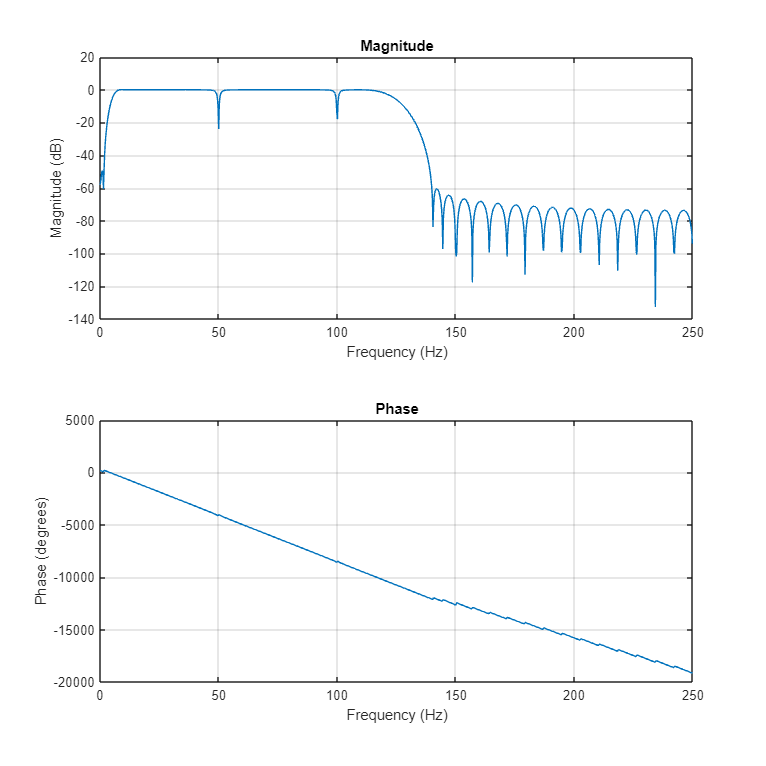

combined_numerator = conv(conv(b_low, b_high), b_comb);
combined_denominator = conv(conv(1, 1), a_comb);

freqz(combined_numerator,combined_denominator,1024,fs);

Initializing Window Designer....

. done. 


nfft = length(after_comb);
[pxx_after_comb,f_after_comb] = periodogram(after_comb,window,nfft,fs);

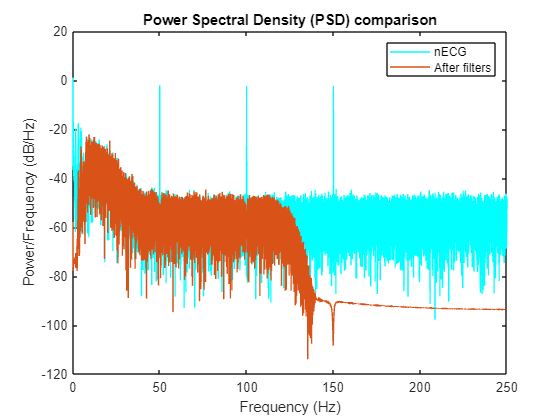


figure;
plot(f_nECG, 10*log10(pxx_nECG),'c'); 
hold on;
plot(f_after_comb, 10*log10(pxx_after_comb)); 
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
legend('nECG','After filters')
title('Power Spectral Density (PSD) comparison');